# Preprocessing Data

We found a huge problem in the format of this that's why our accuracy was high and new images by us was predicted wrong

data1=readtable("C:\Users\WINDOWS 10\Desktop\ASSAAD\University Data Science\Sem 6\Matlab\Projet Finale\Dataset\sign_mnist_train.csv");
head(data1);

    label    pixel1    pixel2    pixel3    pixel4    pixel5    pixel6    pixel7    pixel8    pixel9    pixel10    pixel11    pixel12    pixel13    pixel14    pixel15    pixel16    pixel17    pixel18    pixel19    pixel20    pixel21    pixel22    pixel23    pixel24    pixel25    pixel26    pixel27    pixel28    pixel29    pixel30    pixel31    pixel32    pixel33    pixel34    pixel35   

data2=readtable("C:\Users\WINDOWS 10\Desktop\ASSAAD\University Data Science\Sem 6\Matlab\Projet Finale\Dataset\sign_mnist_test.csv",TreatAsMissing=[' ']);
tail(data2);

    label    pixel1    pixel2    pixel3    pixel4    pixel5    pixel6    pixel7    pixel8    pixel9    pixel10    pixel11    pixel12    pixel13    pixel14    pixel15    pixel16    pixel17    pixel18    pixel19    pixel20    pixel21    pixel22    pixel23    pixel24    pixel25    pixel26    pixel27    pixel28    pixel29    pixel30    pixel31    pixel32    pixel33    pixel34    pixel35   

## joining data

data=[data1;data2];
tail(data);

    label    pixel1    pixel2    pixel3    pixel4    pixel5    pixel6    pixel7    pixel8    pixel9    pixel10    pixel11    pixel12    pixel13    pixel14    pixel15    pixel16    pixel17    pixel18    pixel19    pixel20    pixel21    pixel22    pixel23    pixel24    pixel25    pixel26    pixel27    pixel28    pixel29    pixel30    pixel31    pixel32    pixel33    pixel34    pixel35   

## EDA

minVal = min(data);
maxVal = max(data);
countVal = sum(sum(ismissing(data)))

countVal = 65

Rowswithmissingvalue=any(ismissing(data),2);
sumofrowswithmv=sum(Rowswithmissingvalue)

sumofrowswithmv = 16

size(data)

ans =        34644         785


df=rmmissing(data,1);
Rowswithmissingvalue=any(ismissing(df),2);
sumofrowswithmv=sum(Rowswithmissingvalue)

sumofrowswithmv = 0

## Labels and data splitting into X and Y

labels=df.label;
head(labels);

     3
     6
     2
     2
    13
    16
     8
    22



size(labels)

ans =        34628           1


pixels_df=removevars(df, 'label');
head(pixels_df);

    pixel1    pixel2    pixel3    pixel4    pixel5    pixel6    pixel7    pixel8    pixel9    pixel10    pixel11    pixel12    pixel13    pixel14    pixel15    pixel16    pixel17    pixel18    pixel19    pixel20    pixel21    pixel22    pixel23    pixel24    pixel25    pixel26    pixel27    pixel28    pixel29    pixel30    pixel31    pixel32    pixel33    pixel34    pixel35    pixel36 

size(pixels_df)

ans =        34628         784


# Visualization

### Visualization of Y labels

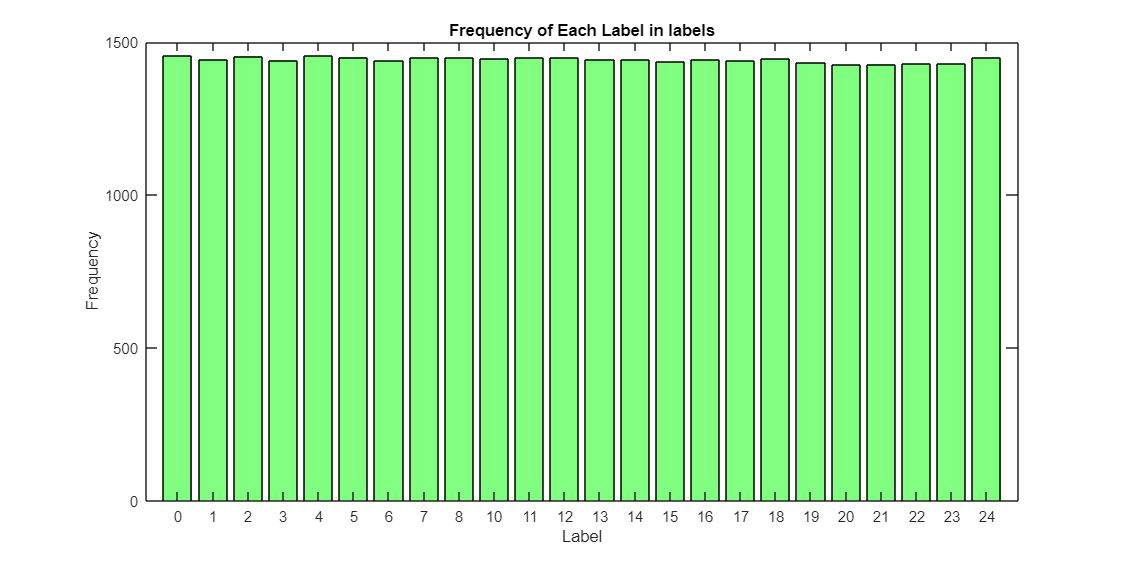

if ~iscategorical(labels)
    cat_label = categorical(labels);
end
labelCounts = countcats(cat_label);

% Get unique labels for the x-axis
uniqueLabels = categories(cat_label);

% Create a bar chart
figure('Position',[300,300,1000,500])
subplot(1,1,1)
bar(uniqueLabels, labelCounts,'FaceColor', [0.5, 1, 0.5])
xlabel('Label')
ylabel('Frequency')
title('Frequency of Each Label in labels')

### Best splitting seed

results_table = table([], [], 'VariableNames', {'RNG', 'Similarity'});
for i=1:65
    rng(i);
    c = cvpartition(labels, 'Holdout', 0.25,'Stratify',true);  
    % Training and test indices
    trainIdx = training(c);
    valtestIdx = test(c);
    % Now you can use these indices to create training and testing sets
    Y_train = labels(trainIdx);
    Y_val_test = labels(valtestIdx);
    c2=cvpartition(Y_val_test,'HoldOut',0.5,'Stratify',true);
    
    % Validation and test indices
    validationIdx = training(c2);
    testIdx = test(c2);
    Y_Validation = labels(validationIdx);
    Y_test = labels(testIdx);
    similarity_score = similarity_of_t_v(Y_test, Y_Validation);
    results_table = [results_table; {i, similarity_score}];
end
results_table=sortrows(results_table,'Similarity','descend');
disp(results_table);

    RNG    Similarity
    ___    __________

    37       0.9454  
    16      0.94331  
    32       0.9397  
    20       0.9395  
    57      0.93823  
    40      0.93819  
    38       0.9376  
    50      0.93748  
    53      0.93726  
    15      0.93571  
    47      0.93534  
    13      0.93393  
    48      0.93319  
     1      0.93315  
     6      0.93266  
    11      0.93136  
    10      0.93121  
    31      0.93113  
    56      0.93042  
    24      0.92962  
    65      0.92887  
     9      0.92848  
     5      0.92704  
     3      0.92662  
    46      0.92658  
    62      0.92651  
    33      0.92648  
    19      0.92601  
    44      0.92596  
    52      0.92516  
    27      0.92453  
     4        0.924  
    39        0.924  
    22      0.92387  
    18       0.9229  
    42      0.92275  
    36      0.92272  
     8      0.92256  
    43      0.92237  
    14       0.9223  
    41 

### Splitting

rng(37);
c = cvpartition(labels, 'Holdout', 0.25,'Stratify',true);  %no need for startify true since the data is already balanced

% Training and test indices
trainIdx = training(c);
valtestIdx = test(c);
%save('split_indices.mat', 'trainIdx', 'testIdx');

% Now you can use these indices to create training and testing sets
X_train = pixels_df(trainIdx, :);
X_val_test = pixels_df(valtestIdx, :);
Y_train = labels(trainIdx);
Y_val_test = labels(valtestIdx);

c2=cvpartition(Y_val_test,'HoldOut',0.5,'Stratify',true);

% Validation and test indices
validationIdx = training(c2);
testIdx = test(c2);

X_Validation = pixels_df(validationIdx, :);
X_test = pixels_df(testIdx, :);
Y_Validation = labels(validationIdx);
Y_test = labels(testIdx);


sizesArray = [size(X_train); size(Y_train); size(X_test); size(Y_test);size(X_Validation);size(Y_Validation)];
disp(sizesArray);

       25971         784
       25971           1
        4328         784
        4328           1
        4329         784
        4329           1



## Visualization of Splitting

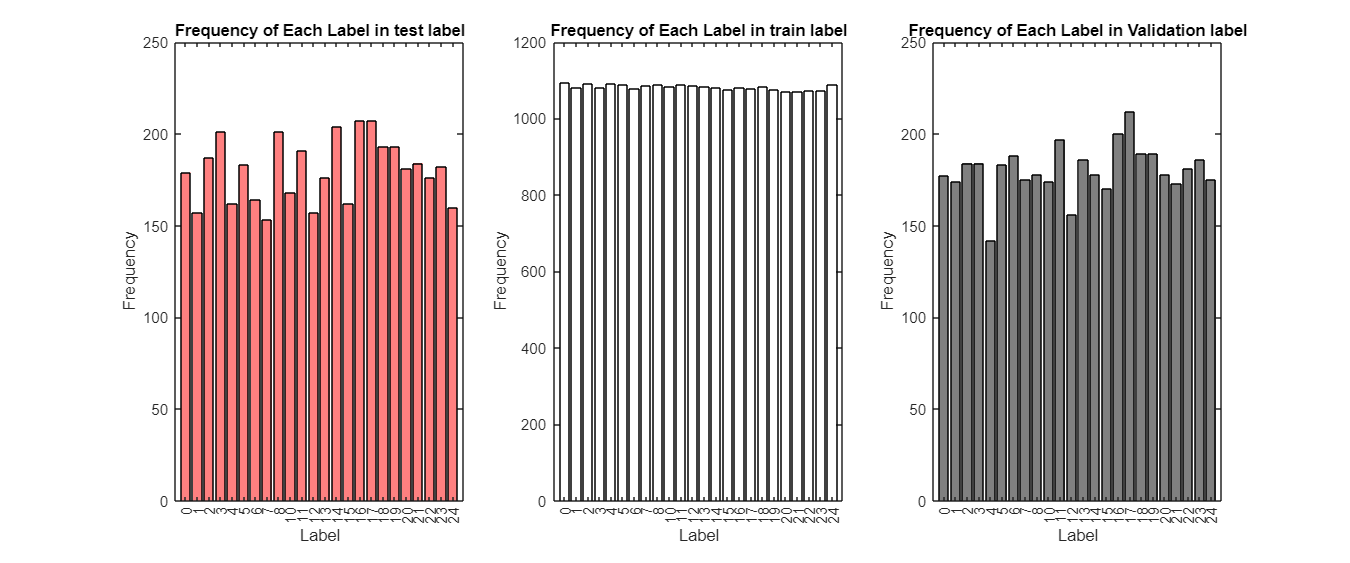

%shape + ratio
figure('Position',[100,100,1200,500])
subplot(1,3,1)
if ~iscategorical(Y_test)
   cat_label = categorical(Y_test);
end
labelCounts = countcats(cat_label);
% Get unique labels for the x-axis
uniqueLabels = categories(cat_label);

% Create a bar chart
bar(uniqueLabels, labelCounts,'FaceColor', [1, 0.5, 0.5])
xlabel('Label')
ylabel('Frequency')
ylim([0,250])
title('Frequency of Each Label in test label')

subplot(1,3,2)
if ~iscategorical(Y_train)
   cat_label = categorical(Y_train);
end
labelCounts = countcats(cat_label);
% Get unique labels for the x-axis
uniqueLabels = categories(cat_label);

% Create a bar chart
bar(uniqueLabels, labelCounts,'FaceColor', [1, 1, 1])
xlabel('Label')
ylabel('Frequency')
title('Frequency of Each Label in train label')

subplot(1,3,3)
if ~iscategorical(Y_Validation)
   cat_label = categorical(Y_Validation);
end
labelCounts = countcats(cat_label);
% Get unique labels for the x-axis
uniqueLabels = categories(cat_label);

% Create a bar chart
bar(uniqueLabels, labelCounts,'FaceColor', [0.5, 0.5, 0.5])
xlabel('Label')
ylabel('Frequency')
ylim([0,250])
title('Frequency of Each Label in Validation label')

### TO 3D and normalization

X_train_arr = table2array(X_train)/255;
disp(size(X_train_arr));

       25971         784



X_train_3D = reshape(X_train_arr, [size(X_train_arr, 1), 28, 28]); %no need for 1 at the end because color scale is already grey
disp(size(X_train_3D))

       25971          28          28



X_test_3D = table2array(X_test)/255;
X_test_3D = reshape(X_test_3D, [size(X_test_3D, 1),28, 28]);
disp(size(X_test_3D));

        4328          28          28



X_Validation_3D=table2array(X_Validation)/255;
X_Validation_3D=reshape(X_Validation_3D, [size(X_Validation_3D, 1),28, 28]);
disp(size(X_Validation_3D));

        4329          28          28



Y_train= categorical(Y_train);
Y_test = categorical(Y_test);
Y_Validation=categorical(Y_Validation);

### Visualization of X images

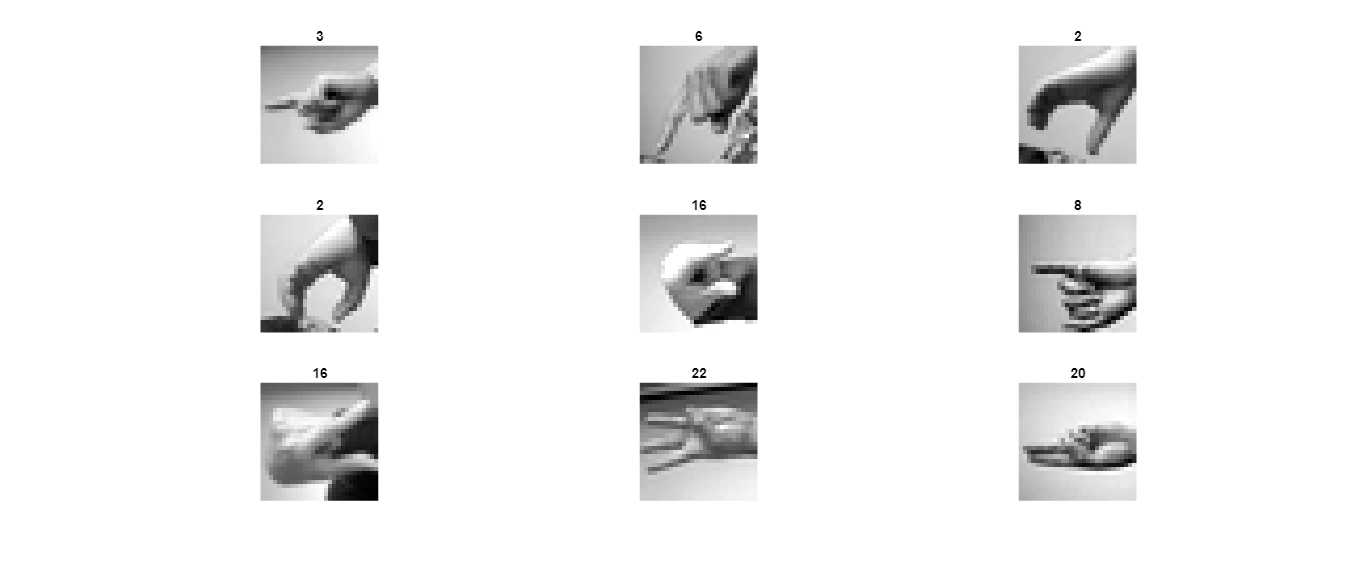

close(gcf);
figure('Position', [100, 100, 1200, 500]);
j=0;
for i=1:9
    j=j+1;
    subplot(3,3,j);
    Ximages=X_test_3D(i,:,:);
    imshow(squeeze(Ximages), []);
    title(string(Y_test(i)))
    
end

### Diff X variations

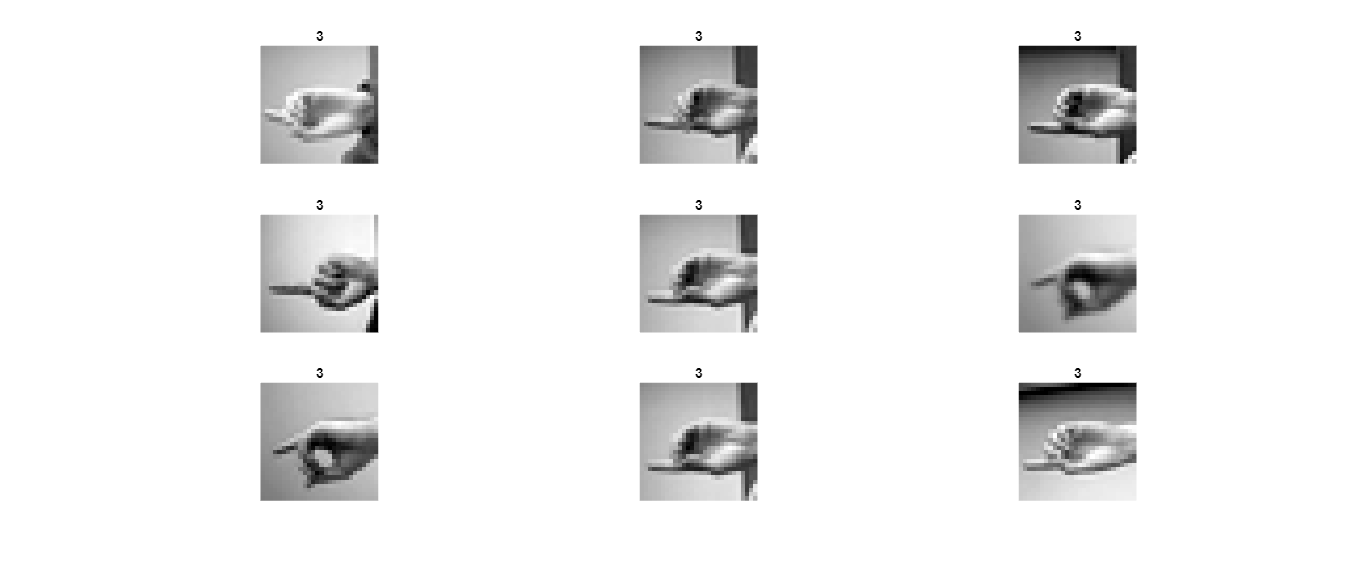

close(gcf);
figure('Position', [100, 100, 1200, 500]);
j=0;
label3=(Y_train==categorical(3));
label3data=X_train_3D(label3,:,:);
for i=200:208
    j=j+1;
    subplot(3,3,j);
    Ximages=label3data(i,:,:);
    imshow(squeeze(Ximages), []);
    title("3")
end

That's the problem that when i introduce new pictures taken from my camera the output is wrong even tho the accuracy is very high because data is well put

### Correction

%X_train_3D=corrected_input_3d(X_train_3D);
%X_test_3D=corrected_input_3d(X_test_3D);
%X_Validation_3D=corrected_input_3d(X_Validation_3D);

size(X_train_3D)
size(X_test_3D)
size(X_Validation_3D)
close(gcf);
figure('Position', [100, 100, 1200, 500]);

ans =        25971          28          28


j=0;

ans =         4328          28          28


for i=10:18

ans =         4329          28          28


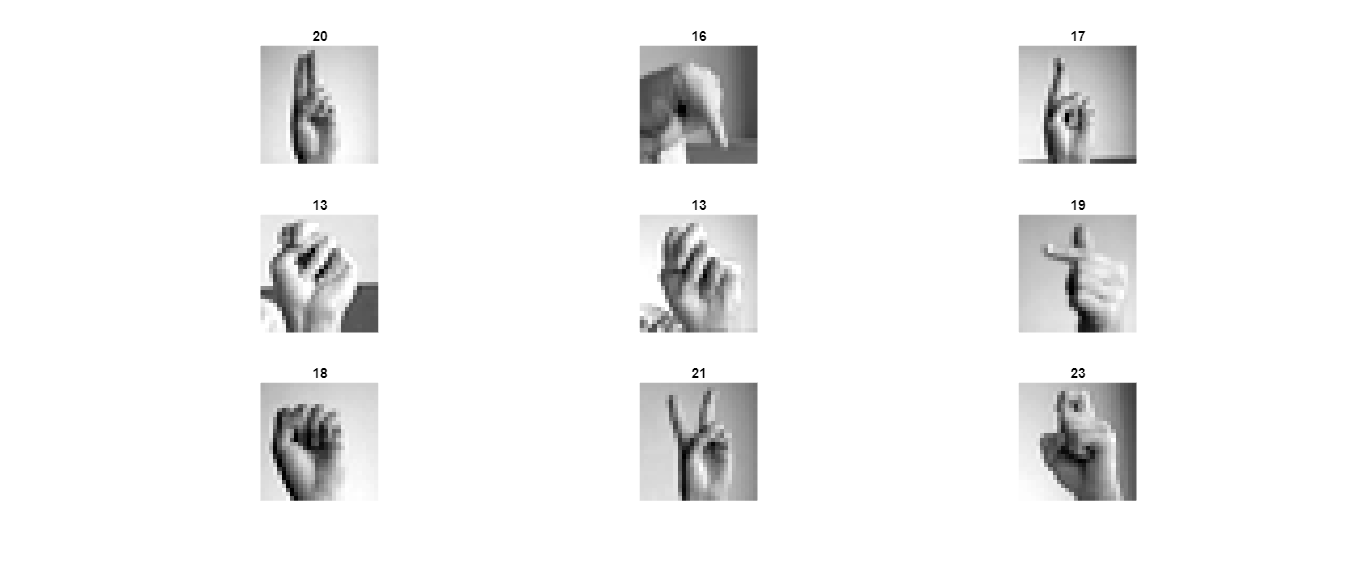

    j=j+1;
    subplot(3,3,j);
    Ximages=X_train_3D(i,:,:);
    imshow(squeeze(Ximages), []);
    title(string(Y_train(i)))
    
end

## Flatting to 784 pixels(training)

% Flatten the 3D image array back into a 2D array
X_train_flattened = reshape(X_train_3D, size(X_train_3D, 1), []);

% Verify the size
disp(size(X_train_flattened));

       25971         784



X_train_table = array2table(X_train_flattened);

% Add the labels back to the table as the first column
train_table = addvars(X_train_table, Y_train, 'Before', 1);

% Define the path
output_csv_path = 'C:\Users\WINDOWS 10\Desktop\ASSAAD\University Data Science\Sem 6\Matlab\Projet Finale\train table.csv';

% Write the table to a CSV file
writetable(train_table, output_csv_path);

## Flatting to 784 pixels(testing)

% Flatten the 3D image array back into a 2D array
X_test_flattened = reshape(X_test_3D, size(X_test_3D, 1), []);

% Verify the size
disp(size(X_test_flattened));

        4328         784



X_test_table = array2table(X_test_flattened);

% Add the labels back to the table as the first column
test_table = addvars(X_test_table, Y_test, 'Before', 1);

% Define the path
output_csv_path = 'C:\Users\WINDOWS 10\Desktop\ASSAAD\University Data Science\Sem 6\Matlab\Projet Finale\test table.csv';

% Write the table to a CSV file
writetable(test_table, output_csv_path);

## Flatting to 784 pixels(validation)

X_Validation_flattened = reshape(X_Validation_3D, size(X_Validation_3D, 1), []);

% Verify the size
disp(size(X_Validation_flattened));

        4329         784



X_Validation_table = array2table(X_Validation_flattened);

% Add the labels back to the table as the first column
Validation_table = addvars(X_Validation_table, Y_Validation, 'Before', 1);

% Define the path
output_csv_path = 'C:\Users\WINDOWS 10\Desktop\ASSAAD\University Data Science\Sem 6\Matlab\Projet Finale\Validation table.csv';

% Write the table to a CSV file
writetable(Validation_table, output_csv_path);

## Visualization after correction

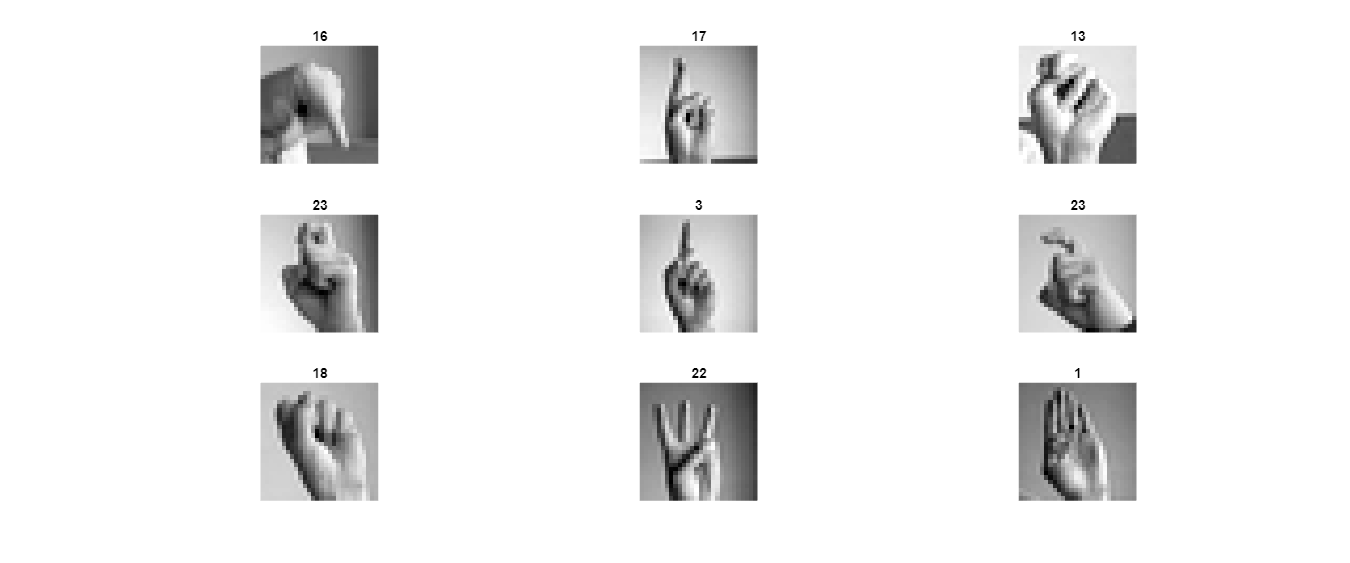

close(gcf);
figure('Position', [100, 100, 1200, 500]);
j=0;
for i=10:18
    j=j+1;
    subplot(3,3,j);
    Ximages=X_test_3D(i,:,:);
    imshow(squeeze(Ximages), []);
    title(string(Y_test(i)))
    
end

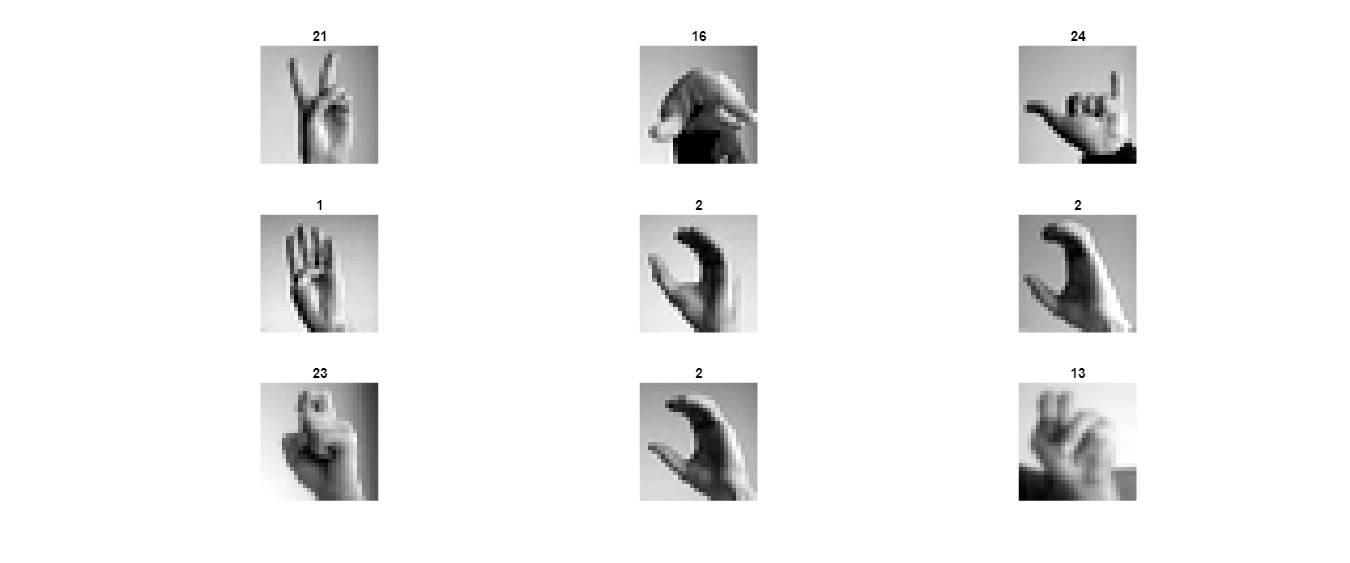

close(gcf);
figure('Position', [100, 100, 1200, 500]);
j=0;
for i=10:18
    j=j+1;
    subplot(3,3,j);
    Ximages=X_Validation_3D(i,:,:);
    imshow(squeeze(Ximages), []);
    title(string(Y_Validation(i)))
    
end

AFTER GOING THROUGHT THE CORRECTION WE CAN MOVE ON TO A NEW FILE AND LOAD THE DATA TO WORK ON IT NOW

## First models

## Data Augmentation and normalization

data augmentation is commonly used in training deep learning models, especially for tasks like image classification, to improve generalization and reduce overfitting.

Augmenting the image dataset to generate new data

The image dataset in also normalised here using the rescale parameter which divides each pixel by 255 such that the pixel values range between 0 to 1.

X_train_t= table2array(X_train)/255;
size(X_train_t)

ans =        25971         784


disp(X_train_t(2,:))

    0.6431    0.6549    0.6667    0.6745    0.6902    0.7020    0.7059    0.7216    0.7255    0.7294    0.7373    0.7412    0.7412    0.7451    0.7490    0.7412    0.7451    0.7451    0.7333    0.7451    0.7529    0.7569    0.7490    0.7490    0.7529    0.7529    0.7608    0.7608    0.6510    0.6627    0.6745    0.6824    0.6941    0.7059    0.7137    0.7255    0.7294    0.7333    0.7451    0.7490    0.7451    0.7490    0.7529    0.7529    0.7608    0.7137    0.5961    0.5725    0.7412    0.7647    0.7608    0.7569    0.7569    0.7608    0.7647    0.7647    0.6549    0.6667    0.6784    0.6902    0.6980    0.7098    0.7176    0.7294    0.7333    0.7373    0.7490    0.7569    0.7529    0.7490    0.7373    0.7569    0.8078    0.7137    0.5333    0.3608    0.6745    0.7686    0.7686    0.7725    0.7647    0.7725    0.7725    0.7686    0.6667    0.6745    0.6863    0.6941    0.7059    0.7216    0.7294    0.7373    0.7373    0.7490    0.7529    0.7569    0.7725    0.7176    0.6000    0.6000

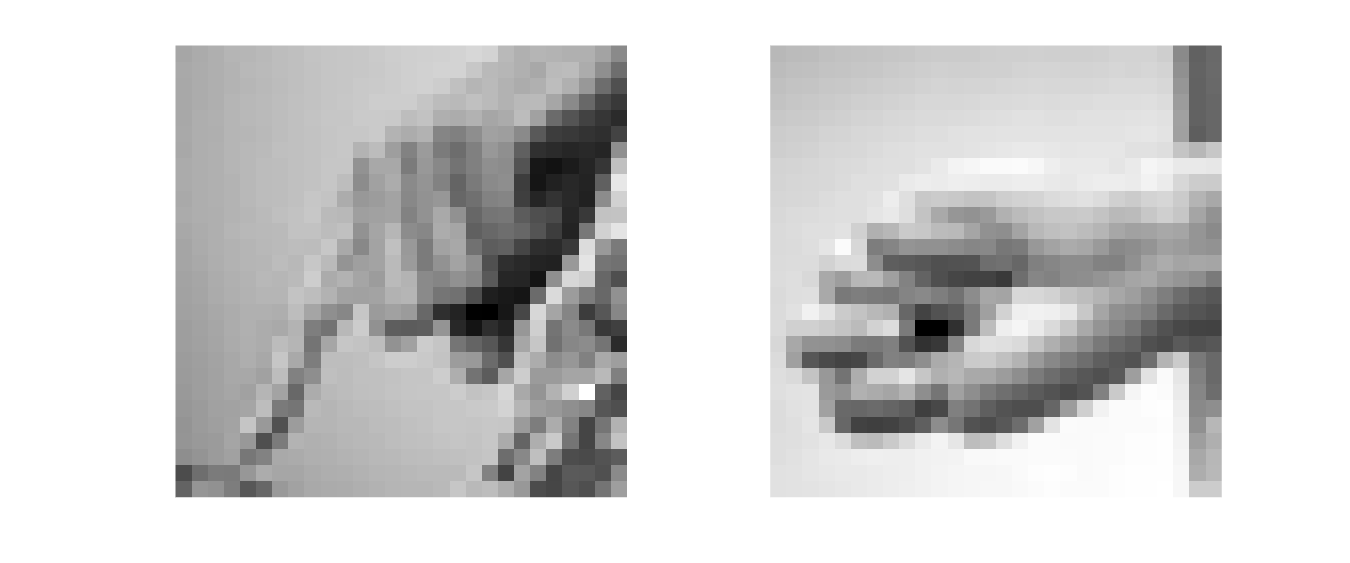

X_train_t = reshape(X_train_t', [28, 28,1,size(X_train_t, 1)]); 
close(gcf);
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1);
beforeimg1=X_train_t(:,:,1);
%sqb=squeeze(beforeimg);
imshow(beforeimg1, []);
subplot(1,2,2);
beforeimg2=X_train_t(:,:,2);
%sqb=squeeze(beforeimg);
imshow(beforeimg2, []);

close(gcf);
X_test_t= table2array(X_test)/255;
X_test_t = reshape(X_test_t', [28, 28, 1,size(X_test_t, 1)]); %it have to be like this 4D because that's the input of a CNN model
X_Validation_t=table2array(X_Validation)/255;
X_Validation_t=reshape(X_Validation_t', [28, 28, 1,size(X_Validation_t, 1)]);
imageAugmenter = imageDataAugmenter('FillValue',0.6,"RandRotation",[-2 2],'RandXTranslation', [-2, 2], ...
    'RandYTranslation', [-2, 2],'RandScale', [0.9,1.1],'RandXShear', [-3, 3], ...
    'RandYShear', [-3, 3]);     
imageSize = [28 28];
auimds = augmentedImageDatastore(imageSize,X_train_t,Y_train,'DataAugmentation',imageAugmenter)

auimds =   augmentedImageDatastore with properties:

         NumObservations: 25971
           MiniBatchSize: 128
        DataAugmentation: [1×1 imageDataAugmenter]
      ColorPreprocessing: 'none'
              OutputSize: [28 28]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


size(Y_train)

ans =        25971           1


size(X_train_t)

ans =           28          28           1       25971


size(Y_test)

ans =         4328           1


size(X_test_t)

ans =           28          28           1        4328


size(X_Validation_t)

ans =           28          28           1        4329


minibatch = preview(auimds) %fetches minibatch of auidms as input and response(batchs are the number of samples)

minibatch = 8×2 table
        input         response
    ______________    ________

    {28×28 double}       6    
    {28×28 double}       13   
    {28×28 double}       16   
    {28×28 double}       8    
    {28×28 double}       22   
    {28×28 double}       3    
    {28×28 double}       3    
    {28×28 double}       10   


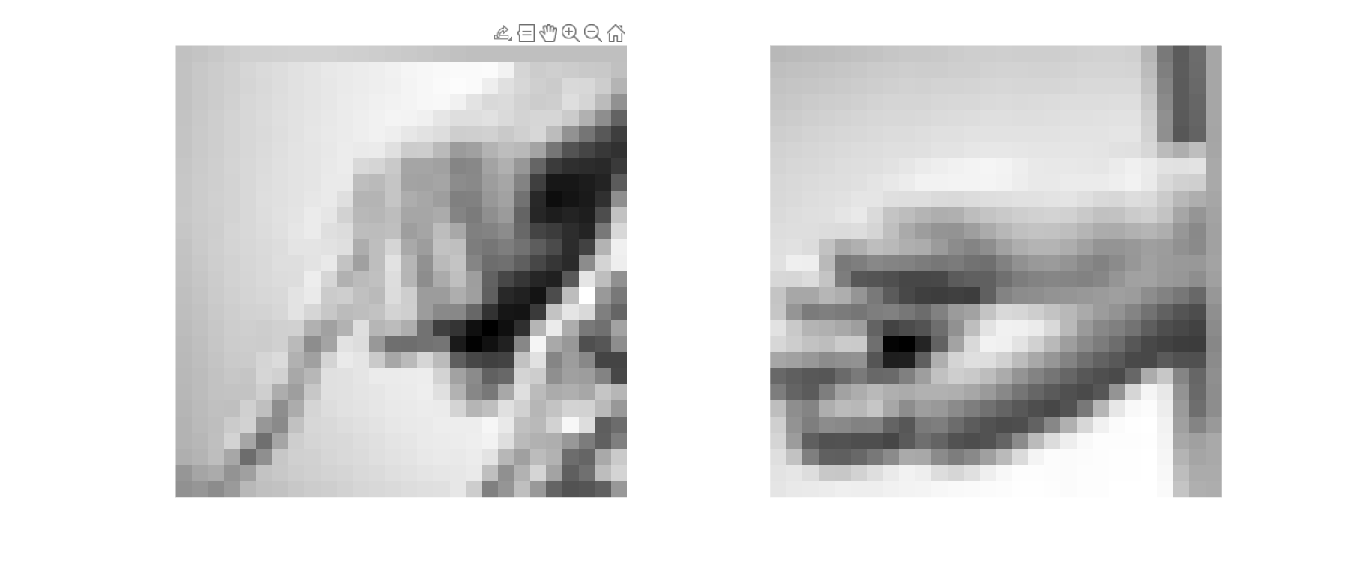

close(gcf);
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1);
afterimg1=minibatch.input{1,1};
%sqb=squeeze(beforeimg);
imshow(afterimg1, []);
subplot(1,2,2);
afterimg2=minibatch.input{2,1};
%sqb=squeeze(beforeimg);
imshow(afterimg2, []);

### CNN modelling

The model consist of :

- Three convolution layer each followed bt MaxPooling for better feature capture

- A dense layer of 512 units

- The output layer with 24 units for 24 different classes

**Convolution layers**

Conv layer 1 -- UNITS - 128 KERNEL SIZE - 5 * 5 STRIDE LENGTH - 1 ACTIVATION - ReLu

Conv layer 2 -- UNITS - 64 KERNEL SIZE - 3 * 3 STRIDE LENGTH - 1 ACTIVATION - ReLu

Conv layer 3 -- UNITS - 32 KERNEL SIZE - 2 * 2 STRIDE LENGTH - 1 ACTIVATION - ReLu

MaxPool layer 1 -- MAX POOL WINDOW - 3 * 3 STRIDE - 2

MaxPool layer 2 -- MAX POOL WINDOW - 2 * 2 STRIDE - 2

MaxPool layer 3 -- MAX POOL WINDOW - 2 * 2 STRIDE - 2

layers = [

model1 = struct with fields:
    net: [1×1 SeriesNetwork]


    imageInputLayer(imageSize)  %setting the image size 28 28 1

    {'net'}



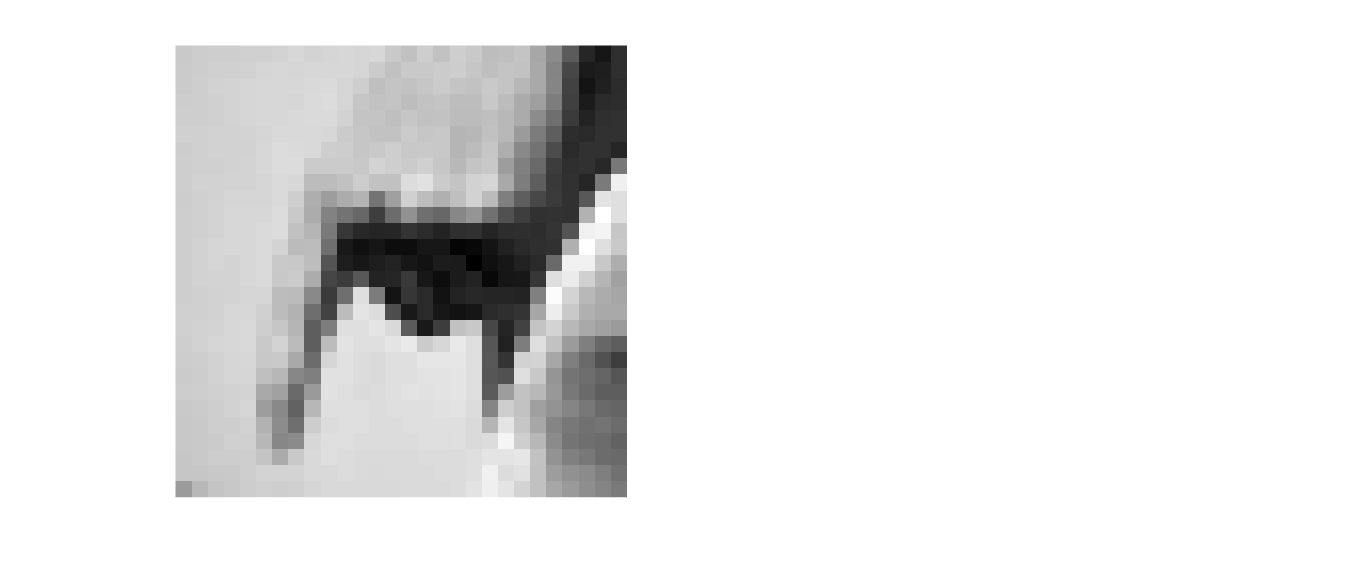

    
    convolution2dLayer(5,128,'Padding','same','Name', 'conv1') %5 is the size,128 filters to extract features , padding same makes the output image size the same as input
    batchNormalizationLayer('Name', 'bn1')  %Normalization layers to make the network faster and more stable for the activation and gradients propagation of a network
    reluLayer('Name', 'relu1')   %this add non-linearity to the system making it either positive or 0 to the output making it easier for the network to solve complex problems
    
    maxPooling2dLayer(3,'Stride',2,'Name', 'maxpool1') %reduce the spatial dimension of the input map:3 will make the model run on 3x3 pixels and choose the max value and stride 2 is for reducing the output map by factor of 2

    
    convolution2dLayer(3,64,'Padding','same','Name', 'conv2')
    batchNormalizationLayer('Name', 'bn2')
    reluLayer('Name', 'relu2')
    

    0.9448



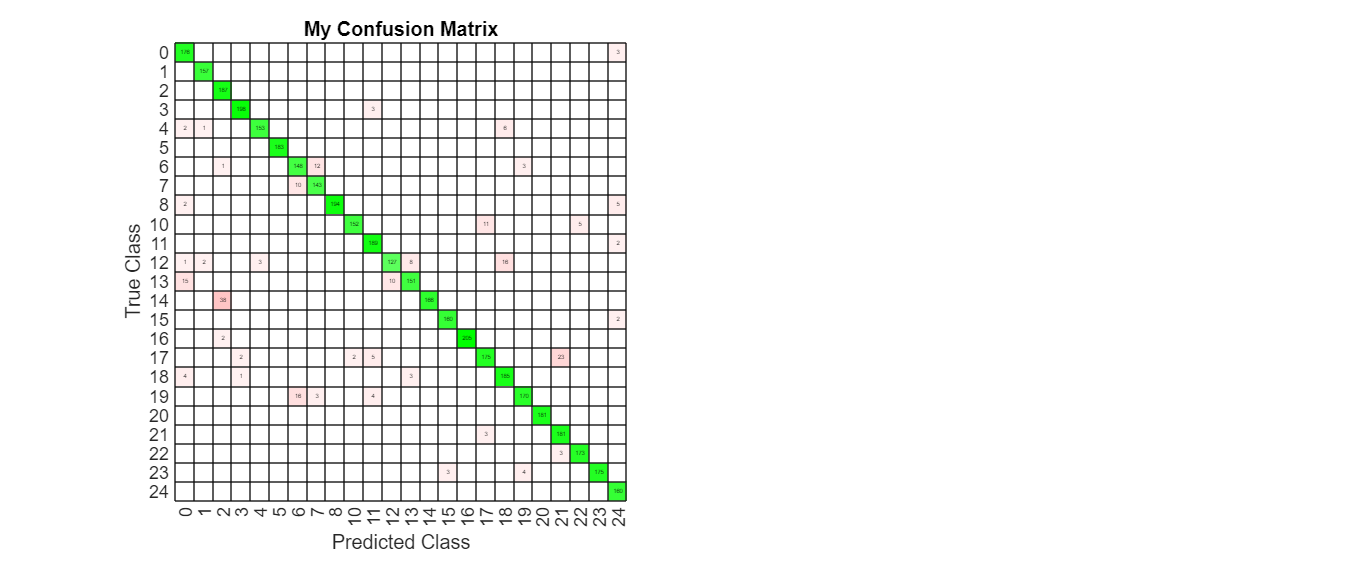

    maxPooling2dLayer(2,'Stride',2,'Name', 'maxpool2')
    
    convolution2dLayer(2,32,'Padding','same','Name', 'conv3')
    batchNormalizationLayer('Name', 'bn3')
    reluLayer('Name', 'relu3')


    maxPooling2dLayer(2,'Stride',2,'Name', 'maxpool3')
    
    fullyConnectedLayer(256,'Name', 'fc1') % First fully connected layer
    reluLayer('Name', 'relu4')
    dropoutLayer(0.25,'Name', 'dropout')

    fullyConnectedLayer(24,'Name', 'fc2') % Second fully connected layer(24 for the classification task)
    softmaxLayer('Name', 'softmax') %flattening the output layer of 24 values in a list that sum to one to know the label of the image

    28    28     3



    classificationLayer]; 
lgraph = layerGraph(layers);
analyzeNetwork(lgraph);

## Model 1 Fitting+Evaluation

% Define training options

    28    28



options = trainingOptions('adam', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 2, ...
    'MiniBatchSize',32,...
    'Shuffle', 'every-epoch', ...

    28    28



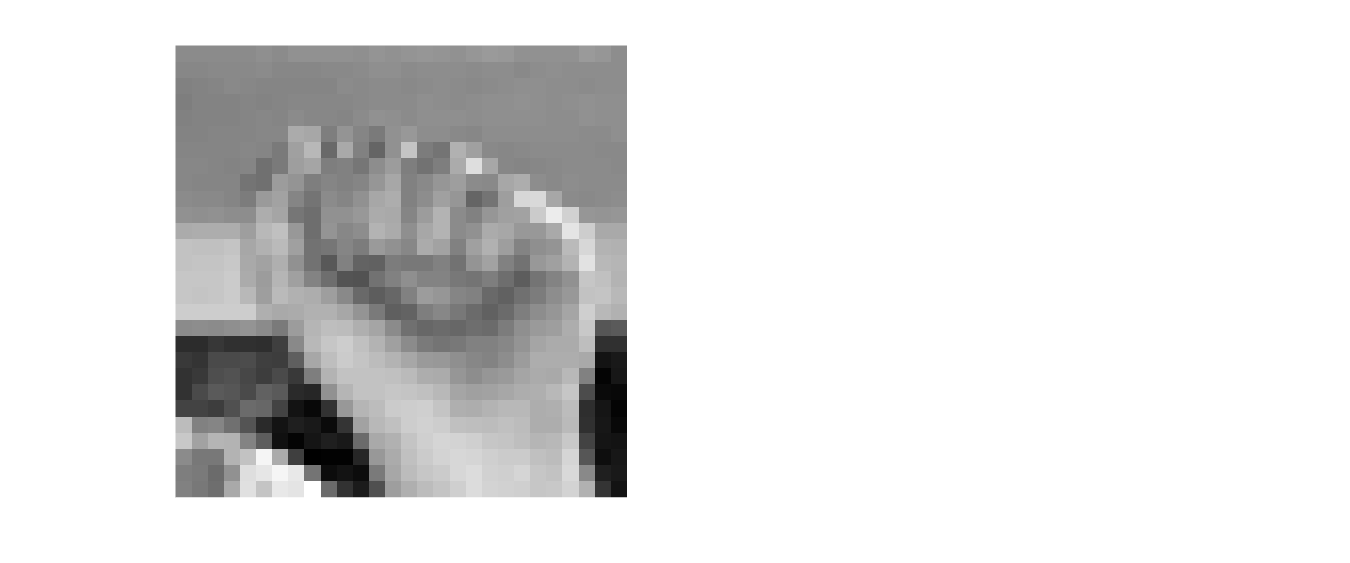

    'ValidationData', {X_Validation_t, Y_Validation}, ...

    'ValidationFrequency', 5, ...
    'Verbose', true, ...

     15 



    'Plots', 'training-progress');
net = trainNetwork(auimds, layers, options);

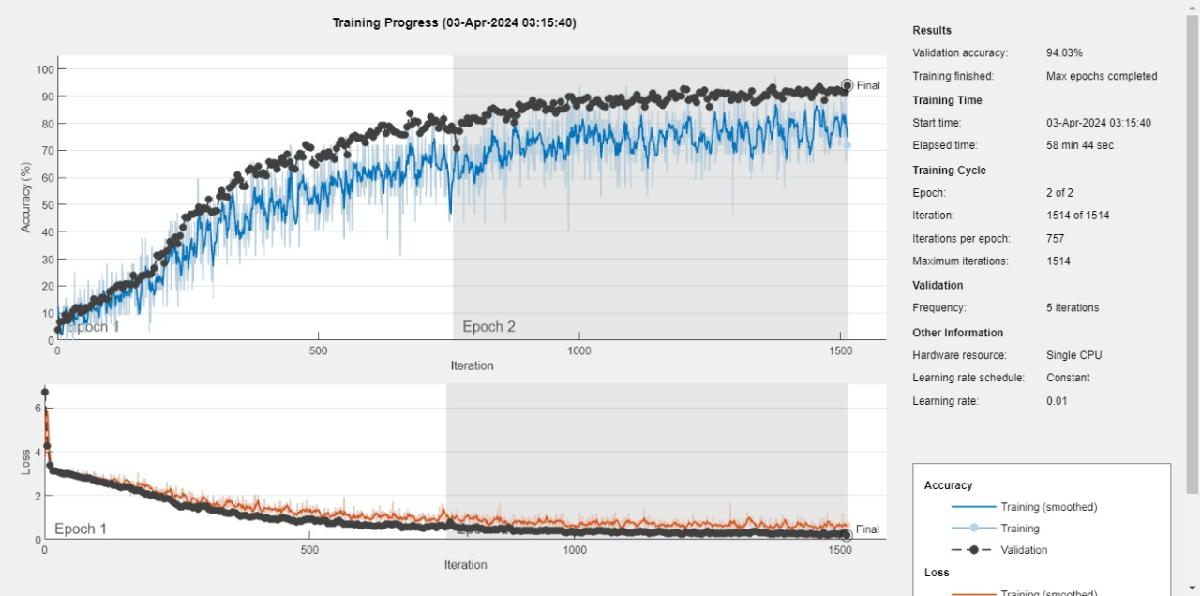

# Saving model

save('myTrainedModel.mat', 'net');

## Loading the model

%loading model
model1=load('myTrainedModel.mat') 
disp(fieldnames(model1));

    28    28     3



cnn_model=model1.net;
close(gcf);
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1);

    28    28



test1=X_test_t(:,:,20);
imshow(test1, []);
predictedLabels = classify(cnn_model, X_test_t);

## Evaluation

accuracy = sum(predictedLabels == Y_test) / numel(Y_test);
disp(accuracy);

    28    28



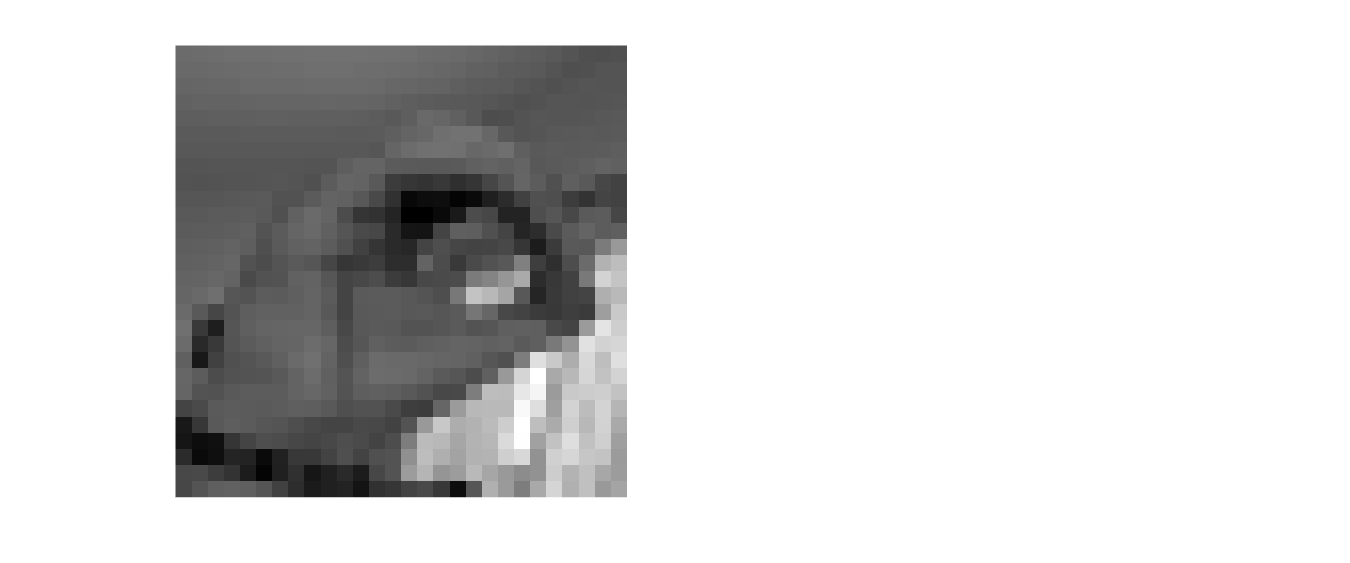

cm = confusionchart(Y_test, predictedLabels);

cm.Title = 'My Confusion Matrix';
cm.FontSize=12;

     2 



cm.DiagonalColor='green';
cm.OffDiagonalColor="red";
[C,order] = confusionmat(Y_test, predictedLabels);
%plotconfusion(predictedLabels,Y_test)

# Predicting new images

Image 1(assaad): label A=0

close(gcf);
newImage = imread('assaad.jpg');
newImage = imresize(newImage, [28, 28]); %resizing the image into 28 by 28 pixels
disp(size(newImage));
if size(newImage, 3) == 3
    newImage = rgb2gray(newImage); %converting to gray scale
end
disp(size(newImage));
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1)
newImage = double(newImage) / 255; %normalizing
newImage = reshape(newImage, [28, 28, 1, 1]); %reshaping into 4D
disp(size(newImage));

       27703         784
       27703           1
        8657         784
        8657           1



imshow(newImage,[]);
predictedLabel1 = classify(cnn_model, newImage);
disp(predictedLabel1);

Image 2(Nourhane):Label O=14

close(gcf);
newImage2 = imread('nourhane.jpeg');
newImage2 = imresize(newImage2, [28, 28]); %resizing the image into 28 by 28 pixels
disp(size(newImage2));
if size(newImage2, 3) == 3
    newImage2 = rgb2gray(newImage2); %converting to gray scale
end
disp(size(newImage2));
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1)
newImage2 = double(newImage2) / 255; %normalizing
newImage2 = reshape(newImage2, [28, 28, 1, 1]); %reshaping into 4D
disp(size(newImage2));
imshow(newImage2,[]);
predictedLabel2 = classify(cnn_model, newImage2);
disp(predictedLabel2);

Predicted as 2=C just like the confusion matrix have showed us he is having huge dificulty in actually predicting similar image

# Model 2

This model was only designed the same as the first model but on 3 epochs

Data augmentation had no RandXReflection

Data was splitted only between 27703 traing and the rest was testing for validation

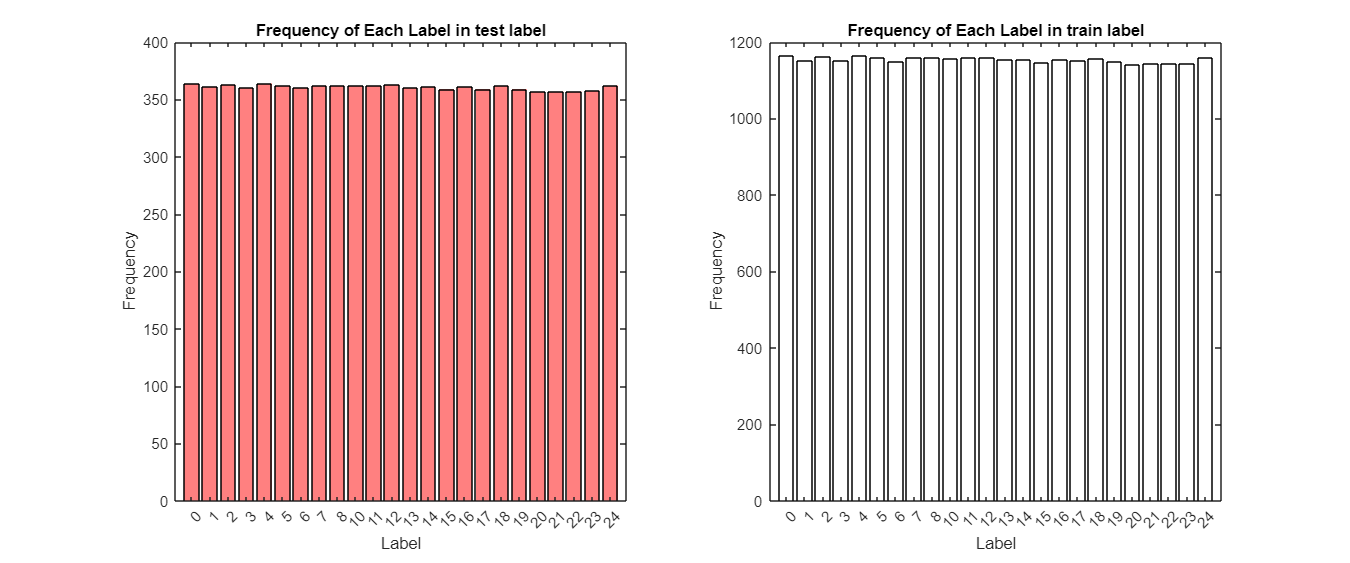

c = cvpartition(labels, 'Holdout', 0.2,'Stratify',true); 

% Training and test indices
trainIdx = training(c);
testIdx = test(c);

% Now you can use these indices to create training and testing sets
X_train_2 = pixels_df(trainIdx, :);
X_test_2 = pixels_df(valtestIdx, :);
Y_train_2 = labels(trainIdx);
Y_test_2 = labels(valtestIdx);
sizesArray = [size(X_train_2); size(Y_train_2); size(X_test_2); size(Y_test_2)];

disp(sizesArray);

## Visualization of splitting

%shape + ratio
figure('Position',[100,100,1200,500])
subplot(1,2,1)
if ~iscategorical(Y_test_2)
   cat_label = categorical(Y_test_2);
end
labelCounts = countcats(cat_label);
% Get unique labels for the x-axis
uniqueLabels = categories(cat_label);


    0.9942



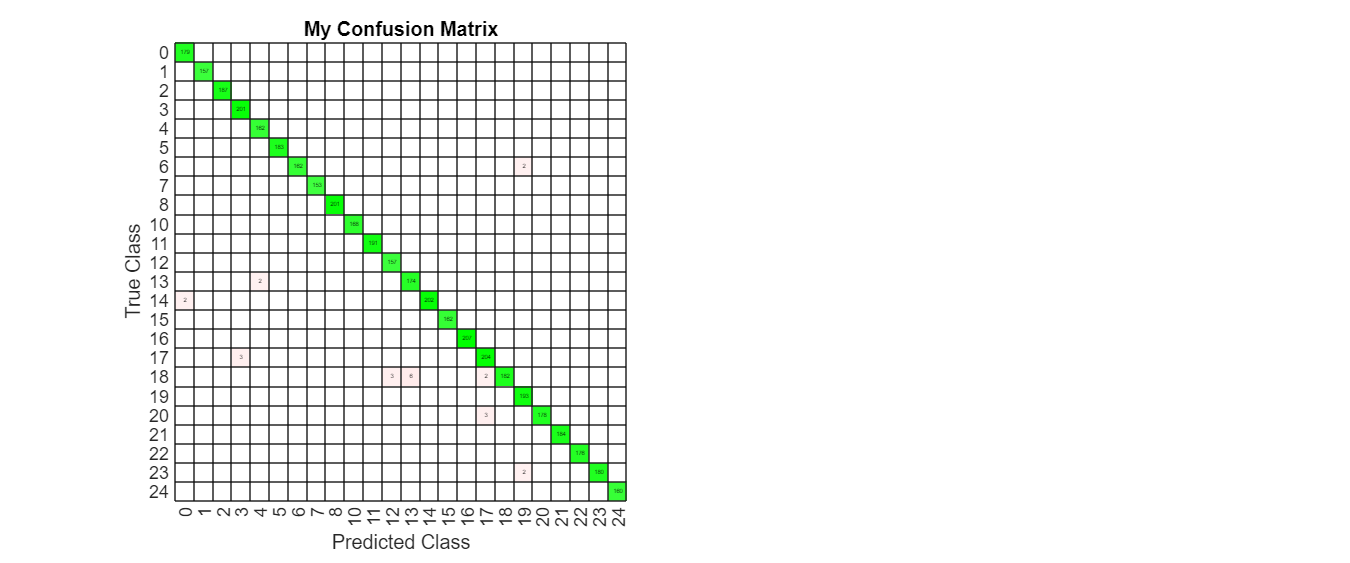

% Create a bar chart
bar(uniqueLabels, labelCounts,'FaceColor', [1, 0.5, 0.5])
xlabel('Label')
ylabel('Frequency')
title('Frequency of Each Label in test label')


subplot(1,2,2)
if ~iscategorical(Y_train_2)
   cat_label = categorical(Y_train_2);
end

labelCounts = countcats(cat_label);
% Get unique labels for the x-axis

     15 



uniqueLabels = categories(cat_label);

% Create a bar chart

bar(uniqueLabels, labelCounts,'FaceColor', [1, 1, 1])
xlabel('Label')

     3 



ylabel('Frequency')
title('Frequency of Each Label in train label')

% Define training options
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 3, ...

ans =        25971         785


    'MiniBatchSize',32,...
    'Shuffle', 'every-epoch', ...

ans =         4328         785


    'ValidationData', {X_test_t, Y_test}, ...
    'ValidationFrequency', 5, ...

ans =         4329         785


    'Verbose', true, ...
    'Plots', 'training-progress');
net = trainNetwork(auimds, layers, options);

loaded=load("trainedCnnModel.mat");

ans =        25971         784


cnn_model2=loaded.net;

     6
    13
    16
     8
    22
     3
     3
    10



predictedlabels2=classify(cnn_model2,X_test_t);

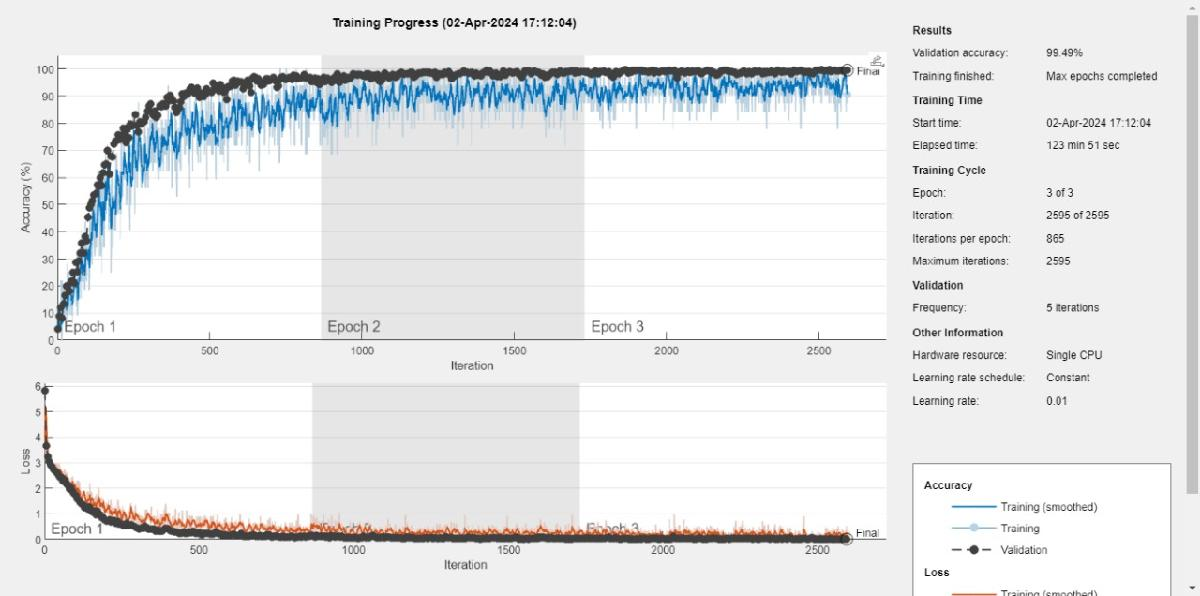

# Evaluation of Model 2:

accuracy = sum(predictedlabels2 == Y_test) / numel(Y_test);
disp(accuracy);

ans =         4328         784


close(gcf);
cm = confusionchart(Y_test, predictedlabels2);
cm.Title = 'My Confusion Matrix';

ans =         4329         784


cm.FontSize=12;
cm.DiagonalColor='green';
cm.OffDiagonalColor="red";
[C,order] = confusionmat(Y_test, predictedLabels);

## New value

imshow(newImage,[]);
predictedLabel1_m2 = classify(cnn_model2, newImage);
disp(predictedLabel1_m2);

Image 2(Nourhane):Label O=14  

imshow(newImage2,[]);
predictedLabel2_m2 = classify(cnn_model2, newImage2);
disp(predictedLabel2_m2);

We can conclude from here that even tho accuracy is 99.4 and confusion matrix is looking good we cannot take it for granted because the model did those assumption on the same data. So for the third model we can now

make the training dataset 75% and 12.5% for both testing-validation.

# LOADING NEW DATASETS AND VISUALIZATION

clear all;
training_data=readtable("C:\Users\User\Desktop\UNIVERSITY\Semestre 6\MATLAB\FINAL\train table.csv");
size(training_data)
testing_data=readtable("C:\Users\User\Desktop\UNIVERSITY\Semestre 6\MATLAB\FINAL\test table.csv");
size(testing_data)
validation_data=readtable("C:\Users\User\Desktop\UNIVERSITY\Semestre 6\MATLAB\FINAL\Validation table.csv");
size(validation_data)

Y_train=training_data.Y_train;
X_train=removevars(training_data, 'Y_train');
size(X_train)
head(Y_train)
Y_test=testing_data.Y_test;
X_test=removevars(testing_data, 'Y_test');
size(X_test)
Y_validation=validation_data.Y_Validation;
X_validation=removevars(validation_data, 'Y_Validation');
size(X_validation)

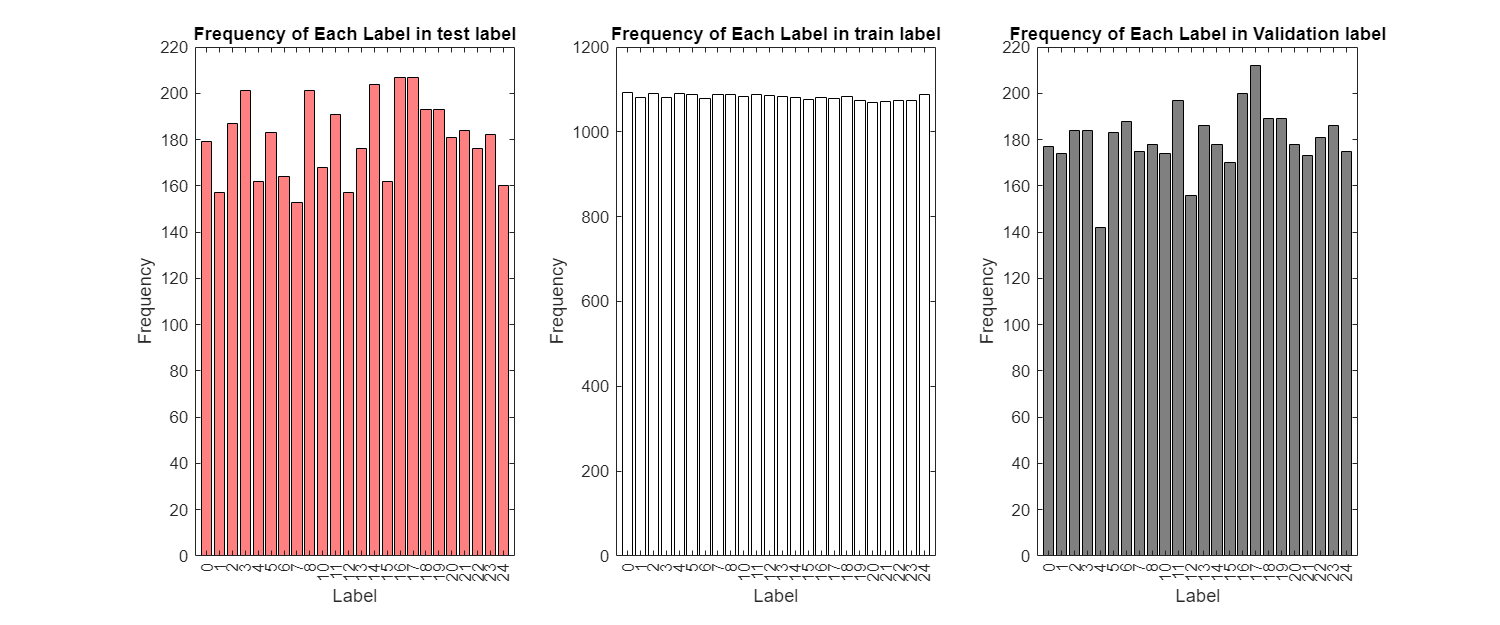

%shape + ratio
figure('Position',[100,100,1200,500])
subplot(1,3,1)
if ~iscategorical(Y_test)
   cat_label = categorical(Y_test);
end
labelCounts = countcats(cat_label);
% Get unique labels for the x-axis
uniqueLabels = categories(cat_label);

% Create a bar chart
bar(uniqueLabels, labelCounts,'FaceColor', [1, 0.5, 0.5])
xlabel('Label')
ylabel('Frequency')
ylim([0,220])
title('Frequency of Each Label in test label')


subplot(1,3,2)
if ~iscategorical(Y_train)
   cat_label = categorical(Y_train);
end
labelCounts = countcats(cat_label);
% Get unique labels for the x-axis

     6 
     13 
     16 
     8 
     22 
     3 
     3 
     10 



uniqueLabels = categories(cat_label);

     13 
     22 
     3 
     3 
     18 
     10 
     13 
     19 




% Create a bar chart
bar(uniqueLabels, labelCounts,'FaceColor', [1, 1, 1])
xlabel('Label')
ylabel('Frequency')
title('Frequency of Each Label in train label')

subplot(1,3,3)
if ~iscategorical(Y_validation)
   cat_label = categorical(Y_validation);
end

auimds =   augmentedImageDatastore with properties:

         NumObservations: 25971
           MiniBatchSize: 128
        DataAugmentation: [1×1 imageDataAugmenter]
      ColorPreprocessing: 'none'
              OutputSize: [28 28]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


labelCounts = countcats(cat_label);
% Get unique labels for the x-axis
uniqueLabels = categories(cat_label);

% Create a bar chart
bar(uniqueLabels, labelCounts,'FaceColor', [0.5, 0.5, 0.5])
xlabel('Label')
ylabel('Frequency')
ylim([0,220])
title('Frequency of Each Label in Validation label')

### TO 4D

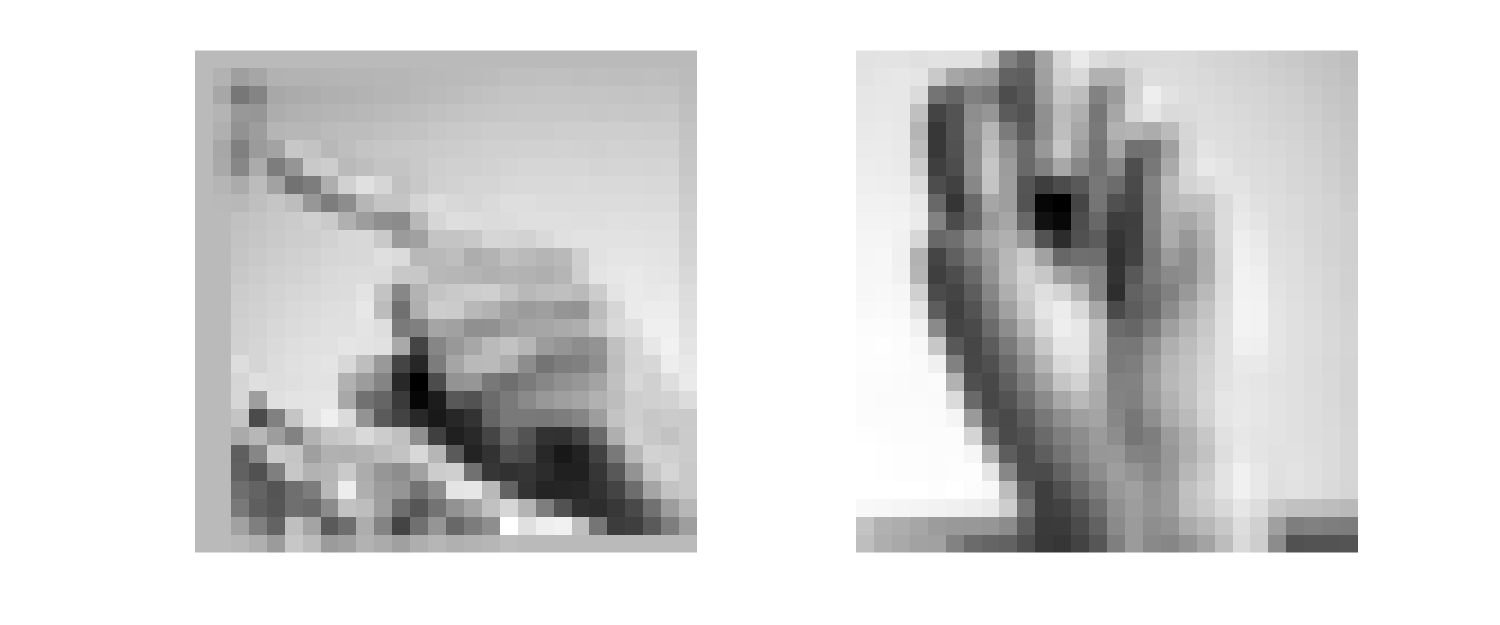

Y_train= categorical(Y_train);

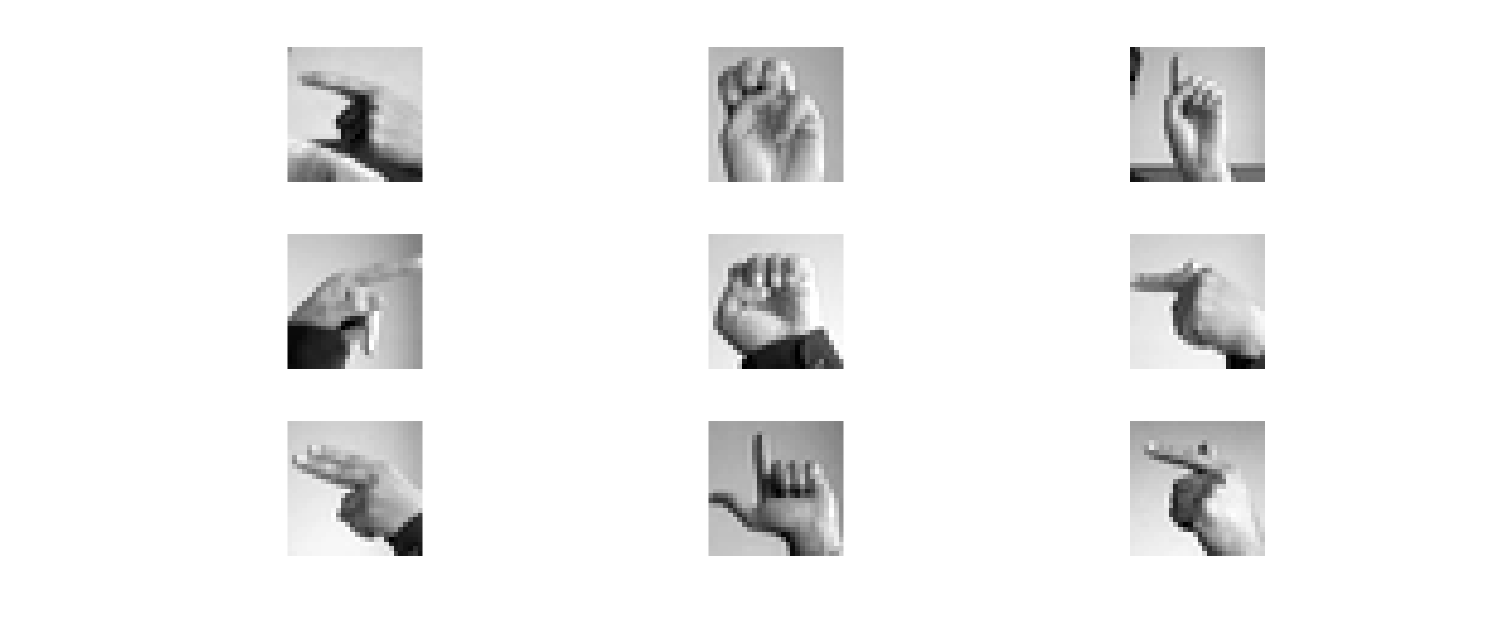

Y_test = categorical(Y_test);
Y_validation=categorical(Y_validation);
head(Y_train);
head(Y_validation);
X_train_t= table2array(X_train);
X_train_t = reshape(X_train_t', [28, 28,1,size(X_train_t, 1)]); 
X_test_t= table2array(X_test);
X_test_t = reshape(X_test_t', [28, 28, 1,size(X_test_t, 1)]); %it have to be like this 4D because that's the input of a CNN model
X_validation_t=table2array(X_validation);
X_validation_t=reshape(X_validation_t', [28, 28, 1,size(X_validation_t, 1)]);
imageAugmenter = imageDataAugmenter('FillValue',0.6,"RandRotation",[-1 1],'RandXTranslation', [-1, 1], ...

    'RandYTranslation', [-1, 1],'RandScale', [0.9,1.1],'RandXShear', [-1, 1], ...
    'RandYShear', [-1, 1]);     
imageSize = [28 28];
auimds = augmentedImageDatastore(imageSize,X_train_t,Y_train,'DataAugmentation',imageAugmenter)
minibatch = preview(auimds); %fetches minibatch of auidms as input and response(batchs are the number of samples)
close(gcf);
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1);
afterimg1=minibatch.input{1,1};
%sqb=squeeze(beforeimg);
imshow(afterimg1, []);
subplot(1,2,2);
afterimg2=minibatch.input{2,1};
%sqb=squeeze(beforeimg);
imshow(afterimg2, []);

### Not augmented values

close(gcf);
figure('Position', [100, 100, 1200, 500]);
j=0;
for i=20:28
    j=j+1;
    subplot(3,3,j);
    beforeimg1=X_test_t(:,:,i);
    imshow(beforeimg1, []);
end

### CNN modelling

The model consist of :

- Three convolution layer each followed bt MaxPooling for better feature capture

- A dense layer of 512 units

- The output layer with 24 units for 24 different classes

**Convolution layers**

Conv layer 1 -- UNITS - 128 KERNEL SIZE - 5 * 5 STRIDE LENGTH - 1 ACTIVATION - ReLu

Conv layer 2 -- UNITS - 64 KERNEL SIZE - 3 * 3 STRIDE LENGTH - 1 ACTIVATION - ReLu

Conv layer 3 -- UNITS - 32 KERNEL SIZE - 2 * 2 STRIDE LENGTH - 1 ACTIVATION - ReLu

MaxPool layer 1 -- MAX POOL WINDOW - 3 * 3 STRIDE - 2

MaxPool layer 2 -- MAX POOL WINDOW - 2 * 2 STRIDE - 2

MaxPool layer 3 -- MAX POOL WINDOW - 2 * 2 STRIDE - 2

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:17 |        0.00% |        5.52% |       4.1430 |       3.4662 |          0.0010 |
|       1 |           5 |       00:00:29 |        9.38% |       11.18% |       3.2011 |       3.2157 |          0.0010 |
|       1 |          10 |       00:00:39 |       18.75% |       22.85% |       3.0705 |       2.8496 |          0.0010 |
|       1 |          15 |       00:00:49 |       25.00% |       29.29% |       2.7528 |   

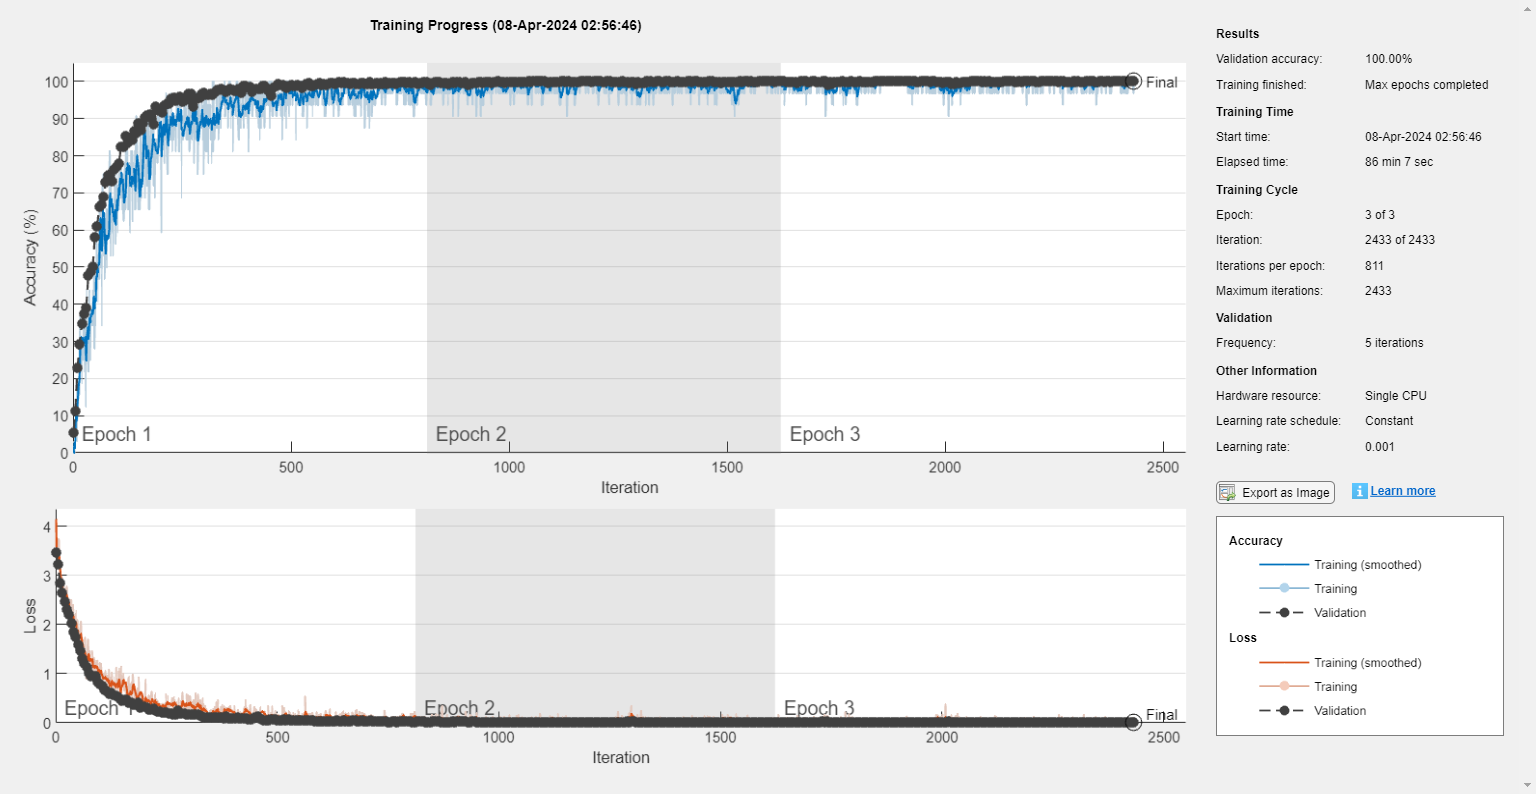

layers = [

    imageInputLayer(imageSize)  %setting the image size 28 28 1
    
    convolution2dLayer(5,128,'Padding','same','Name', 'conv1') %5 is the size,128 filters to extract features , padding same makes the output image size the same as input
    batchNormalizationLayer('Name', 'bn1')  %Normalization layers to make the network faster and more stable for the activation and gradients propagation of a network
    reluLayer('Name', 'relu1')   %this add non-linearity to the system making it either positive or 0 to the output making it easier for the network to solve complex problems
    
    maxPooling2dLayer(3,'Stride',2,'Name', 'maxpool1') %reduce the spatial dimension of the input map:3 will make the model run on 3x3 pixels and choose the max value and stride 2 is for reducing the output map by factor of 2
    
    convolution2dLayer(3,64,'Padding','same','Name', 'conv2')
    batchNormalizationLayer('Name', 'bn2')
    reluLayer('Name', 'relu2')
    
    maxPooling2dLayer(2,'Stride',2,'Name', 'maxpool2')
    
    convolution2dLayer(2,32,'Padding','same','Name', 'conv3')
    batchNormalizationLayer('Name', 'bn3')
    reluLayer('Name', 'relu3')

    maxPooling2dLayer(2,'Stride',2,'Name', 'maxpool3')
    
    fullyConnectedLayer(256,'Name', 'fc1') % First fully connected layer
    reluLayer('Name', 'relu4')
    dropoutLayer(0.25,'Name', 'dropout')

    fullyConnectedLayer(24,'Name', 'fc2') % Second fully connected layer(24 for the classification task)
    softmaxLayer('Name', 'softmax') %flattening the output layer of 24 values in a list that sum to one to know the label of the image
    classificationLayer]; 
lgraph = layerGraph(layers);
analyzeNetwork(lgraph);

% Define training options
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 3, ...
    'MiniBatchSize',32,...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {X_validation_t, Y_validation}, ...
    'ValidationFrequency', 5, ...
    'Verbose', true, ...
    'Plots', 'training-progress');
net3 = trainNetwork(auimds, layers, options);

# Saving model

save('model3.mat', 'net3');

## Loading the model

%loading model
model1=load('myTrainedModel.mat') 
disp(fieldnames(model1));
cnn_model=model1.net;
close(gcf);
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1);
test1=X_test_t(:,:,20);
imshow(test1, []);
predictedLabels = classify(cnn_model, X_test_t);

## Evaluation

accuracy = sum(predictedLabels == Y_test) / numel(Y_test);
disp(accuracy);
cm = confusionchart(Y_test, predictedLabels);
cm.Title = 'My Confusion Matrix';
cm.FontSize=12;
cm.DiagonalColor='green';
cm.OffDiagonalColor="red";
[C,order] = confusionmat(Y_test, predictedLabels);
%plotconfusion(predictedLabels,Y_test)

# Predicting new images

Image 1(assaad): label A=0

close(gcf);
newImage = imread('assaad.jpg');
newImage = imresize(newImage, [28, 28]); %resizing the image into 28 by 28 pixels
disp(size(newImage));
if size(newImage, 3) == 3
    newImage = rgb2gray(newImage); %converting to gray scale
end
disp(size(newImage));
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1)
newImage = double(newImage) / 255; %normalizing
newImage = reshape(newImage, [28, 28, 1, 1]); %reshaping into 4D
disp(size(newImage));
imshow(newImage,[]);
predictedLabel1 = classify(cnn_model, newImage);
disp(predictedLabel1);

Image 2(Nourhane):Label O=14

close(gcf);
newImage2 = imread('nourhane.jpeg');
newImage2 = imresize(newImage2, [28, 28]); %resizing the image into 28 by 28 pixels
disp(size(newImage2));
if size(newImage2, 3) == 3
    newImage2 = rgb2gray(newImage2); %converting to gray scale
end
disp(size(newImage2));
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1)
newImage2 = double(newImage2) / 255; %normalizing
newImage2 = reshape(newImage2, [28, 28, 1, 1]); %reshaping into 4D
disp(size(newImage2));
imshow(newImage2,[]);
predictedLabel2 = classify(cnn_model, newImage2);
disp(predictedLabel2);

Predicted as 2=C just like the confusion matrix have showed us he is having huge dificulty in actually predicting similar image

function corrected_input=corrected_input_3d(INPUT_3D)
rotation_angle = -90; % or whatever angle you need
output_size = [28, 28];
% Apply rotation to each image in the training set
for idx = 1:size(INPUT_3D, 1)
    rotated_image = imrotate(squeeze(INPUT_3D(idx, :, :)), rotation_angle, 'crop');
    % Crop the image if necessary to make sure it's the same size as before
    cropped_image = imresize(rotated_image, output_size);
    corrected_input(idx, :, :) = cropped_image;
end
end


function  similarity_score=similarity_of_t_v(testlb,vallb)
    categories1=unique(categorical(testlb));
    simlist=[];
    for j=1:length(categories1)
        cat=categories1(j);
        v_c=sum(categorical(vallb)==cat);
        t_c=sum(categorical(testlb)==cat);
        siml=min(v_c,t_c)/max(v_c,t_c);
        simlist=[simlist,siml];
    end
    similarity_score = mean(simlist);
end